**リアプノフの安定判別法**

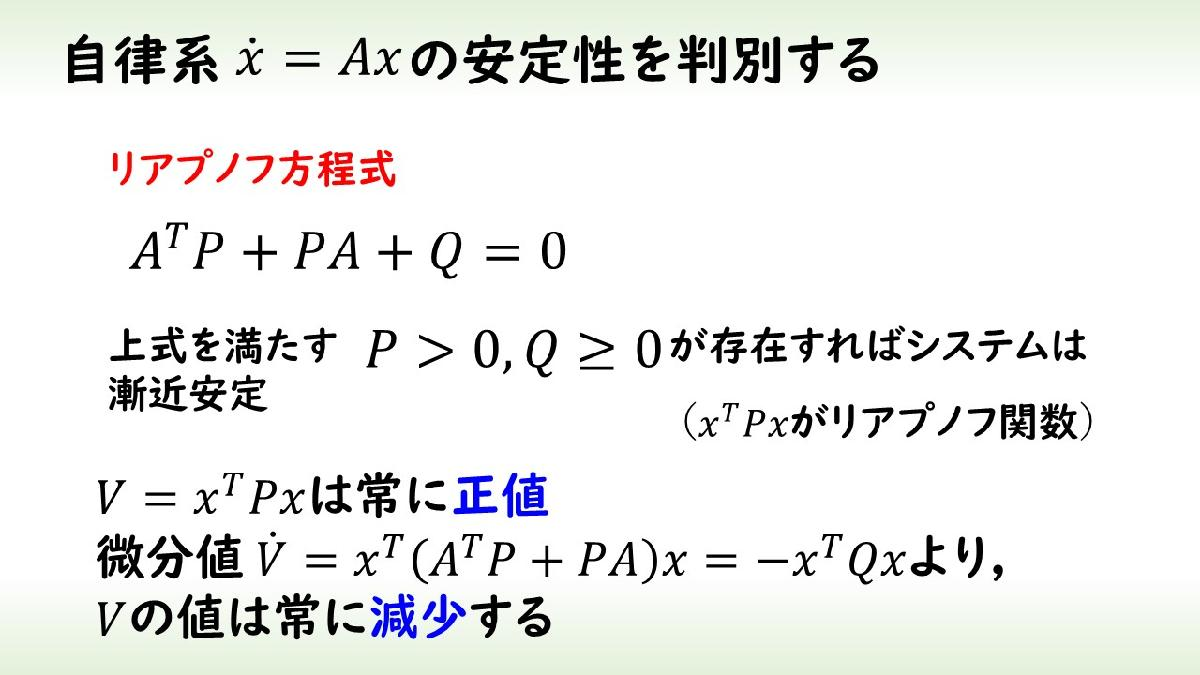

T = 0:0.01:4;

global A;
A = [0 1;-8.6 -3.4]

A =          0    1.0000
   -8.6000   -3.4000


eig(A)

ans =   -1.7000 + 2.3896i
  -1.7000 - 2.3896i



for i = 1:20
x0=[1*sin(2*pi*i/20),1*cos(2*pi*i/20)];
[t,x]=ode45(@function01,T,x0);

図１：状態量（x1）

figure(1)
plot(t,x(:,1))
hold on

図２：状態量（x2）

figure(2)
plot(t,x(:,2))
hold on

図３：状態軌道（初期：黒，T=0.5：緑，T=1：赤）

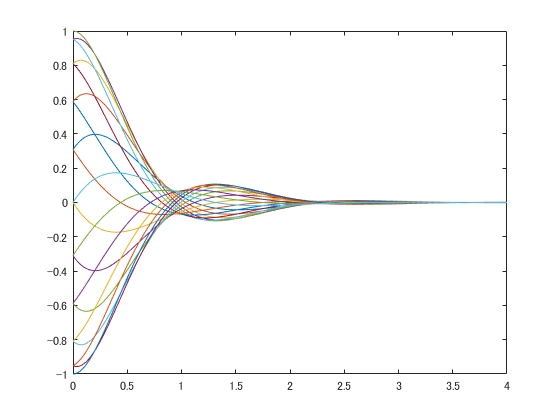

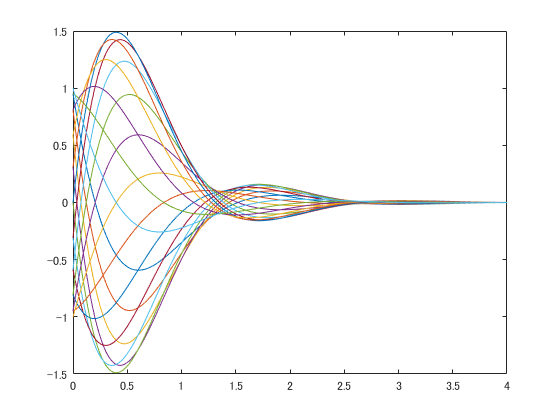

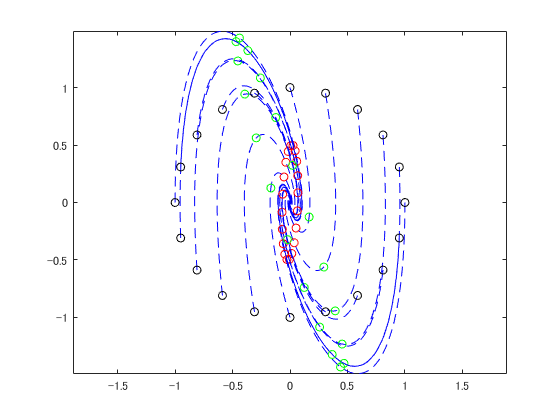

figure(3)
plot(x(:,1),x(:,2),'b--')
hold on
plot(x(101,1),x(101,2),'ro')
hold on
plot(x(51,1),x(51,2),'go')
hold on
plot(x(1,1),x(1,2),'ko')
hold on
axis equal
end

リアプノフ方程式A'P+PA+Q=0の解 （ただしQ = I）

Q = eye(2)

Q =      1     0
     0     1


P=lyap(A',Q)

P =     1.6094    0.0581
    0.0581    0.1642


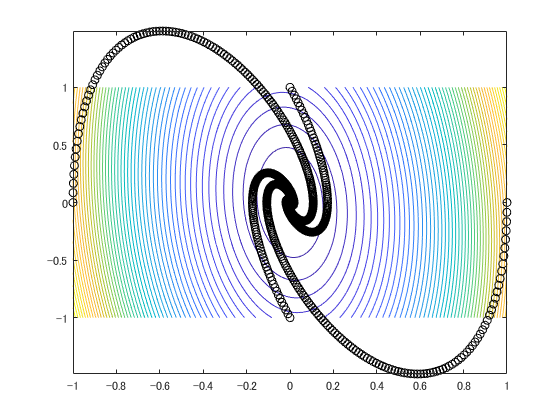

[X1,X2] = meshgrid(-1:0.02:1);
Z = P(1,1)*X1.^2 + P(2,2)*X2.^2 + 2*P(1,2)*X1.*X2;
figure(4)
contour(X1,X2,Z,50);
hold on
plot(x(:,1),x(:,2),'ko')
hold on
figure(5)
contour3(X1,X2,Z,50);
hold on
plot3(x(:,1),x(:,2),P(1,1)*x(:,1).^2+P(2,2)*x(:,2).^2+2*P(1,2)*x(:,1).*x(:,2),'ko')
hold on

x0=[1*sin(2*pi*25/100),1*cos(2*pi*25/100)];
[t,x]=ode45(@function01,T,x0);
figure(4)
plot(x(:,1),x(:,2),'ko')
hold on
figure(5)
plot3(x(:,1),x(:,2),P(1,1)*x(:,1).^2+P(2,2)*x(:,2).^2+2*P(1,2)*x(:,1).*x(:,2),'ko')
hold on

x0=[1*sin(2*pi*50/100),1*cos(2*pi*50/100)];
[t,x]=ode45(@function01,T,x0);
figure(4)
plot(x(:,1),x(:,2),'ko')
hold on
figure(5)
plot3(x(:,1),x(:,2),P(1,1)*x(:,1).^2+P(2,2)*x(:,2).^2+2*P(1,2)*x(:,1).*x(:,2),'ko')
hold on

x0=[1*sin(2*pi*75/100),1*cos(2*pi*75/100)];
[t,x]=ode45(@function01,T,x0);
figure(4)
plot(x(:,1),x(:,2),'ko')
hold on

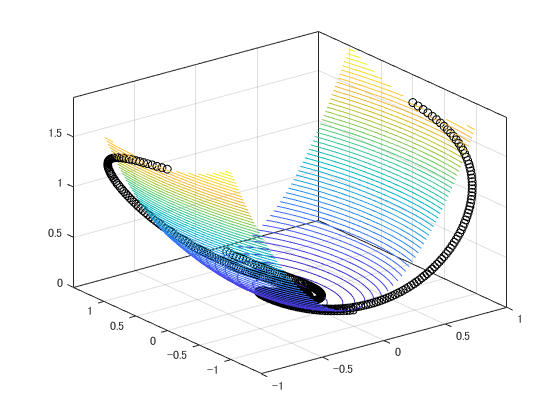

figure(5)
plot3(x(:,1),x(:,2),P(1,1)*x(:,1).^2+P(2,2)*x(:,2).^2+2*P(1,2)*x(:,1).*x(:,2),'ko')
hold on

function dx = function01(~,x)
global A;
dx = zeros(2,1);
dx(1) = A(1,:)*x;
dx(2) = A(2,:)*x;
end